# Load modules and cleanups

clear
close all
mrstModule add upr ad-props ad-blackoil deckformat ad-core mrst-gui linearsolvers   
mrstVerbose on


## Output directory and options

%Paths
outputDir = 'C:\Users\huaba0661\OneDrive - University of Bergen\Desktop\mrst-2024b\FluidFlower\mrstExample\Test.Vol1';
mesh_path = 'C:\Users\huaba0661\OneDrive - University of Bergen\Desktop\mrst-2024b\FluidFlower\mrstExample\mesh';
Fluid_path = 'C:\Users\huaba0661\OneDrive - University of Bergen\Desktop\mrst-2024b\FluidFlower\mrstExample\fluid_props';

%Options
mesh = 'coarse';                    % 'coarse' or 'fine'
wellno = 2;                         % 1 or 2 injectros   
depth = '1km';                      % 1km or surface (fluidflower)

if strcmp(depth, 'surface')
    rate = 8;                       %max inj rate (ml/min) (por que 8????)
    fault_pc = 'low';               % low or default  (que cambia??)
    folderName = ['example_mesh_', mesh, '_rate_', num2str(rate), ...
                  '_faultPc_' fault_pc '_depth_' depth];
    disp('******************************************************')
    warning('This will take a long time to run. Are you sure?')
    disp('Press any key to continue. You can cancel now or later with Ctrl + C')
    disp('******************************************************')
    pause 
elseif strcmp(depth,'1km')
        rate = 80;
        folderName = ['example_mesh_', mesh, '_rate_', num2str(rate), ...
                  '_depth_' depth];
end

% Plots
fig3D = @() figure('Position', [0, 0, 1300, 650]);
alpha = 0.6;
cmap  = jet*alpha + (1-alpha);
setAxProps = @(ax) set(ax, 'View'              , [60, 20]         , ...
                           'PlotBoxAspectRatio', [4.40, 1.86, 1.00], ...
                           'Projection'        , 'Perspective'     , ...
                           'Box'               , 'on'              , ...
                           'ColorMap'          , cmap              );


## Mesh

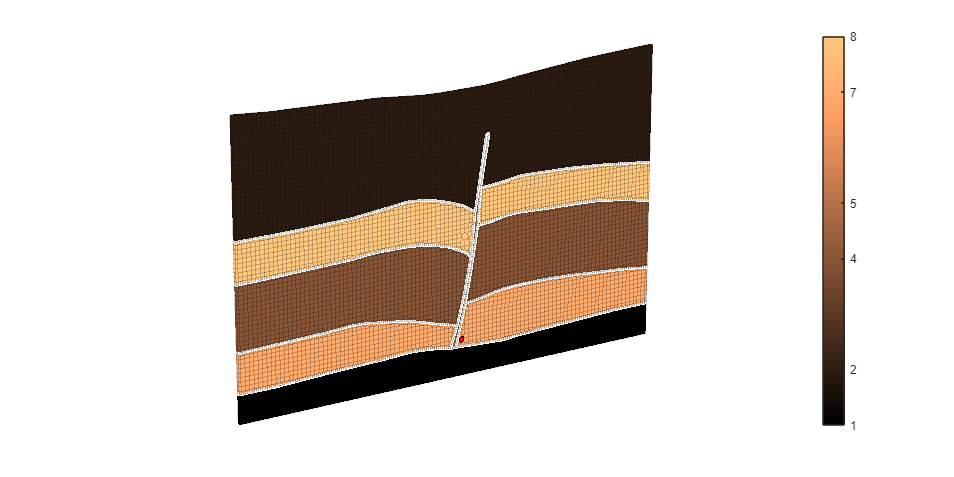

if strcmp(mesh, 'coarse') && strcmp(depth, 'surface')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize3cm.mat'));
elseif strcmp(mesh, 'fine') && strcmp(depth, 'surface')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize1cm.mat'));
elseif strcmp(mesh, 'coarse') && strcmp(depth, '1km')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize3cm_depth1km.mat'));
elseif strcmp(mesh, 'fine') && strcmp(depth, '1km')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize1cm_depth1km.mat'));
end

sealID = [1 3 5 8];
faultID = 6;
unitGroups = {5, [4 7], [1 8], [2 9], 3, 6};    % bottom to top, fault at the end
G = G_dat.G;

% Plot
fig3D();
%plotCellData(G, G_dat.p)
Ncompart = max(G_dat.p);
cmap = copper(Ncompart);
colr = [1, 7, 4, 8, 2, 5];
for n=1:numel(unitGroups)
    plotCellData(G, colr(n)*ones(sum(ismember(G_dat.p, unitGroups{n})), 1), ...
                 ismember(G_dat.p, unitGroups{n}), 'edgealpha', 0.2)
end
plotGrid(G, find(G_dat.wellNo==1), 'facecolor', 'r')
outlineCoarseGrid(G, G_dat.compartID,'EdgeColor','w','LineWidth',2);
setAxProps(gca), %camlight();
colormap(copper); c = colorbar; set(c, 'YTick', sort(colr));
axis equal off

## Rock

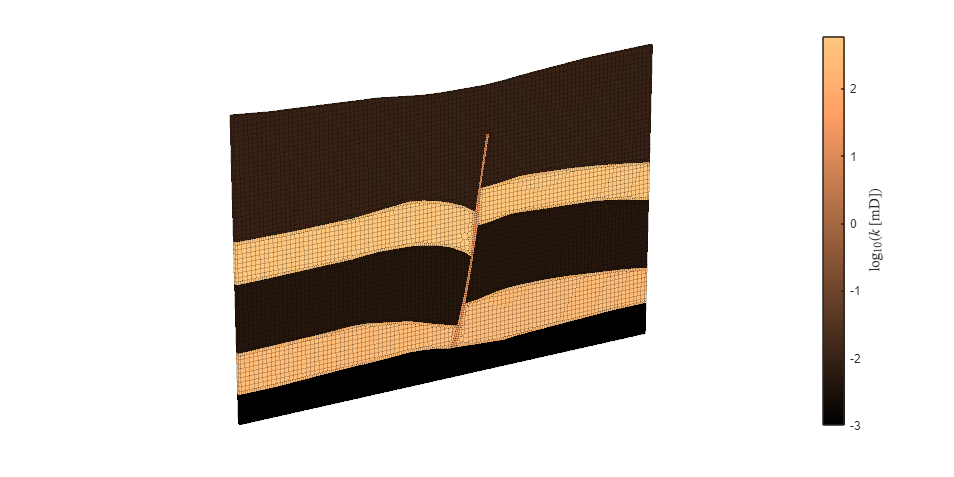

rock.poro = nan(G.cells.num, 1);
rock.perm = nan(G.cells.num, 1);    % isotropic
if strcmp(depth, '1km')
    poroMean = [0.1, 0.3, 0.2, 0.35, 0.27, 0.2];
    permMean = [1e-3, 300, 5e-3, 600, 1e-2, 50];   % [mD]
else
    poroMean = [0.25, 0.4, 0.3, 0.45, 0.27, 0.35];
    permMean = [100, 6000, 1000, 10000, 500, 3000];   % [mD]
end
variation = [];
%rng(S);
for n=1:numel(unitGroups)
    % Cell ids of corresponding unit
    cid = ismember(G_dat.compartID, unitGroups{n});
    nc = sum(cid);
    
    % Porosity and Permeability
    if strcmp(variation, 'randm')   % random
        S = rng;
        warning(['If simulation cancelled and restarted, you have to' ...
                 'uncomment rng(S) above'])
        r = 0.02;                   % half range for poro
        logr = 0.2;                 % half range for perm
    else
        r = 0;
        logr = 0;
    end
    rock.poro(cid) = (poroMean(n) - r) + rand(nc, 1)*(2*r);
    rock.perm(cid) = 10.^(rand(nc, 1)*(2*logr) + (log10(permMean(n)) - logr));                                            
end
rock.perm = rock.perm*(milli*darcy); % MRST requires SI units

% Plot permeability
fig3D(); plotCellData(G, log10(rock.perm/(milli*darcy)), 'edgealpha', 0.2)
setAxProps(gca), colormap(copper), 
c = colorbar; c.Label.Interpreter = 'latex'; c.Label.FontSize = 11;
c.Label.String = '$\log_{10}(k $ [mD])';
axis equal off

## Fluids

% Define 3 Saturation regions
rock.regions.saturation = ones(G.cells.num, 1);        % reservoir units
rock.regions.saturation(ismember(G_dat.compartID, sealID)) = 2;
rock.regions.saturation(ismember(G_dat.compartID, faultID)) = 3;

% Define 1 Region for compressibility
rock.regions.rocknum = ones(G.cells.num,1); 

% Load fluid deck from .DATA (ECLIPSE-type) input file and initialize fluid
% The PVT properties of the fluids are obtained by running a thermodynamic 
% model based on Duan & Sun, Chemical Geology (2003) and Spycher et al., 
% Geochimica et cosmochimica acta (2003) fomulations. The implementation
% is described in Hassanzadeh et al., IJGGC (2008).
if strcmp(depth, 'surface')
    if strcmp(fault_pc, 'low')
        fn  = fullfile(Fluid_path, 'example_co2brine_shallow_3regions_lowPce.DATA');
    else
        fn  = fullfile(Fluid_path, 'example_co2brine_shallow_3regions.DATA');
    end
elseif strcmp(depth, '1km')
    fn  = fullfile(Fluid_path, 'example_co2brine_1kmDepth_3regions.DATA');
end

deck = convertDeckUnits(readEclipseDeck(fn));

No converter needed in section 'REGIONS'.
No converter needed in section 'SUMMARY'.
No converter needed in section 'PCUNIT'.



deck.REGIONS.ROCKNUM = rock.regions.rocknum;
fluid = initDeckADIFluid(deck);       